max_rate = 0.05;
track_len = 120;
n_cells = 100;
hwhm = 15;

field_std = hwhm * 2 / 2.355;
m = sort(rand(n_cells, 1)) * track_len;
rate_func = @(x) max_rate.*exp(-((x-m)./field_std).^2./2);

dt = seconds(1/20);
sess_time = hours(0.5);
max_v = 30; %cm/s

t = seconds(seconds(0):dt:sess_time); %s
x_traj = track_len .* sin(max_v./track_len .* t).^2;

response_sample = @(x) poissrnd(rate_func(x));
X_indep = response_sample(x_traj);

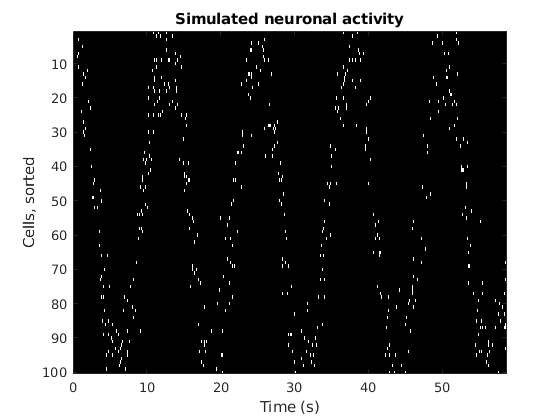

figure;
imagesc(t, 1:n_cells, X_indep~=0);

xlim([-0.0 58.8])
xlabel 'Time (s)'
ylabel 'Cells, sorted'
title 'Simulated neuronal activity'
colormap gray

n_cells_dep = 400;
V_dep = randn(n_cells_dep, n_cells)./sqrt(n_cells) * X_indep;
X_dep = poissrnd(max(V_dep, 0));

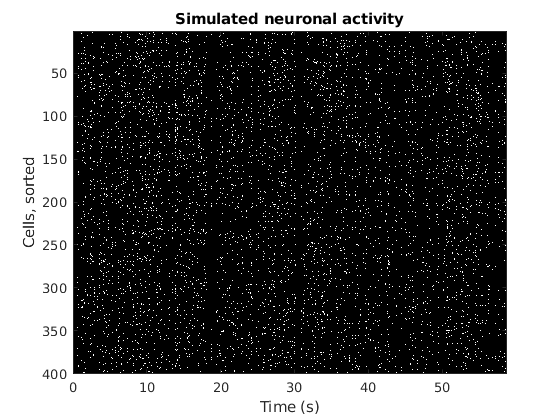

figure;
imagesc(t, 1:n_cells_dep, X_dep ~= 0);

xlim([-0.0 58.8])
xlabel 'Time (s)'
ylabel 'Cells, sorted'
title 'Simulated neuronal activity'
colormap gray

X_both = [X_indep ; X_dep];

[n_neu, mse, mse_sh, fr, gof] = decode_series(X_indep, x_traj, 1, 30, 16, fastpnb, true);

     1     2     3     4     5     6     7     8     9    11    13    15    17    20    24    28



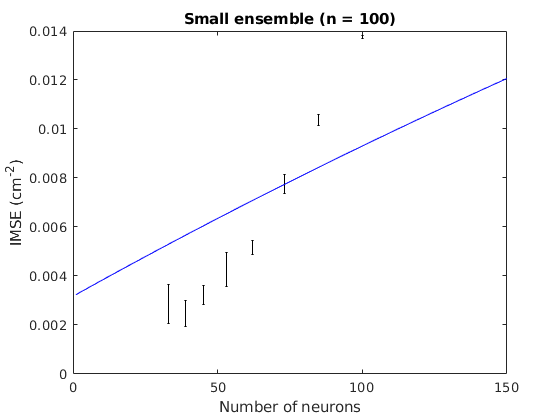

figure;
ep(n_neu, 1./mse, 'k');
hold on;
huge_n = 150;
plot(1:huge_n, fr(1:huge_n), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title 'Small independent ensemble (n = 100)'

[n_neu, mse, mse_sh, fr, gof] = decode_series(X_dep, x_traj, 1, 30, 16, fastpnb, false);

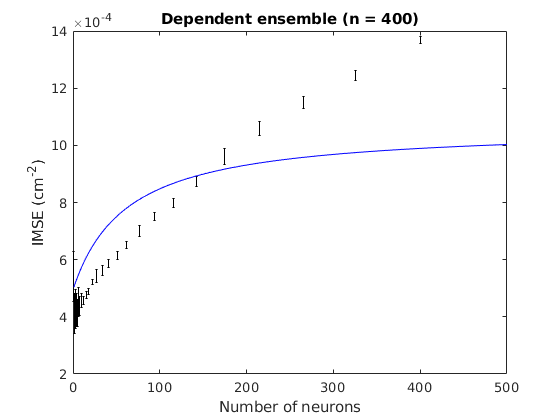

figure;
ep(n_neu, 1./mse, 'k');
hold on;
huge_n = 500;
plot(1:huge_n, fr(1:huge_n), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title 'Dependent ensemble (n = 400)'

[n_neu, mse, mse_sh, fr, gof] = decode_series(X_both, x_traj, 1, 30, 16, fastpnb, false);

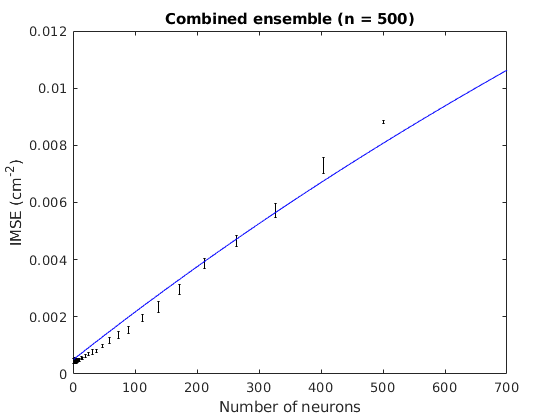

figure;
ep(n_neu, 1./mse, 'k');
hold on;
huge_n = 700;
plot(1:huge_n, fr(1:huge_n), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title 'Combined ensemble (n = 500)'

## Functions

function [n_neu, mse, mse_sh, fr, gof] = decode_series(X_noise, x_traj, n_min, approx_samp, n_reps, alg, linear_only)
progress = true;
position = [x_traj(:), 0*x_traj(:)];
dt_opts = DecodeTensor.default_opt;
[~,~,tr_s,tr_e,tr_dir,tr_bins,~] = DecodeTensor.new_sel(position, dt_opts);

data_tensor = DecodeTensor.construct_tensor(X_noise.', tr_bins, dt_opts.n_bins, tr_s, tr_e);

n_cells = size(X_noise, 1);
n_neu = unique(round(logspace(log10(n_min),log10(n_cells),approx_samp)));
%n_neu = unique([1,opt.approx_samp:opt.approx_samp:n_cells,n_cells]);
NN = numel(n_neu);

if progress
    %progressbar('reps...', 'neu...');
    %hbar = parfor_progressbar(n_reps*NN,'Computing...');
    WaitMessage = parfor_wait(n_reps*NN, 'ReportInterval', ceil(n_reps*NN/100));
else
    WaitMessage = [];
end
[mse, mse_sh] = deal(zeros(n_reps, numel(n_neu)));

parfor r_ix = 1:n_reps
    for n_ix = 1:NN

        err_res = DecodeTensor.decode_all(data_tensor,...
            tr_dir, dt_opts.bin_width, alg, n_neu(n_ix), []);

        mse(r_ix, n_ix) = err_res.MSE.unshuffled;
        mse_sh(r_ix, n_ix) = err_res.MSE.shuffled;

        if progress
            %progressbar([],n_ix/numel(n_neu));
            %hbar.iterate(1);
            WaitMessage.Send;
        end
    end
    if progress
        %progressbar(r_ix/n_reps, []);
        %hbar.iterate(1);
    end
end
if progress
    %close(hbar);
    WaitMessage.Destroy;
end

if linear_only
    imse = 1./mse;

    low_bound = 0.0012;
    high_bound = 0.0462;

    good_vals = all(imse > low_bound,1) & all(imse < high_bound,1);

    if any(~good_vals)
        warning('Removed some values.');
        disp(n_neu(~good_vals));
    end

    n_neu = n_neu(good_vals);
    mse = mse(:, good_vals);
    mse_sh = mse_sh(:, good_vals);

    %load('fit_stability_analysis_workspace.mat', 'sigma_vals');
    %load('fit_stability_analysis_workspace.mat', 'rmse_vals');
    %[r_sorted, ord] = unique(rmse_vals);
    %sigma_lookup = @(r) interp1(r_sorted, sigma_vals(ord), r, 'linear', "extrap");
    %converter = @(m) sigma_lookup(sqrt(m)).^2;
    %mse = converter(mse);
    %mse_sh = converter(mse_sh);
end

if numel(n_neu) > 2
    [fr, gof] = createFit_intercept(n_neu, mean(1./mse, 1));
    %[fr, gof] = createFit_infoSaturation(n_neu, mean(1./mse, 1));
else
    fr = [];
    gof = [];
end
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end

function ep_(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none");
end

function ci = get_ci(fit_mdl, varname)
names = coeffnames(fit_mdl);
idx = find(strcmp(names, varname));
assert(numel(idx) == 1, 'Variable not found');

q = confint(fit_mdl);
q = q(:,idx);
ci = (q(2) - q(1))/2;
end
